# Root Finding - IC Activity 9.16

## Bungee Jump

Graphically find the root of the bungee jumper velocity @ time t = 4 for masses of 50 kg to 200 kg. Find which mass is at terminal velocity if the initial velo was 36 m/s and the coefficient of drag is 0.25.

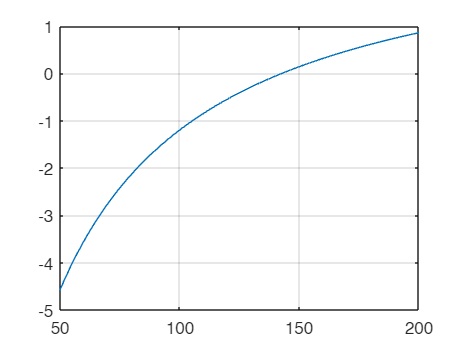

clear; clc;
cd = 0.25; g = 9.81; v = 36; t = 4;
mp = linspace(50,200); % mass of person
fp = sqrt(g*mp/cd).*tanh(sqrt(g*cd./mp)*t)-v;
plot(mp,fp),grid;


% Best guess of root: ~ 145 kg
% Check: (should be about 0)
fp = sqrt(g*145/cd).*tanh(sqrt(g*cd./145)*t)-v

fp = 0.0456

#### Bisection

func = @(x) sin(10*x)+cos(3*x);
% plot(x, func);

Unrecognized function or variable 'x'.

x1 = 3; xu = 6; maxit = 50; es = 0.0001;
[root,ea,iter] = bisect(func,x1,xu,es,maxit)

#### Random Incremental Search Method

xb = incsearch(func,x1,xu)